# **静磁场中超导体的性质观察**

**        超导材料处于超导态时，只要外加磁场不超过一定值，磁力线不能透入，超导材料内的磁场恒为零，即**$\mu_{\;} =0$，**从而任何磁场进入不到柱体内部。**

**        用pdetool仿真：**

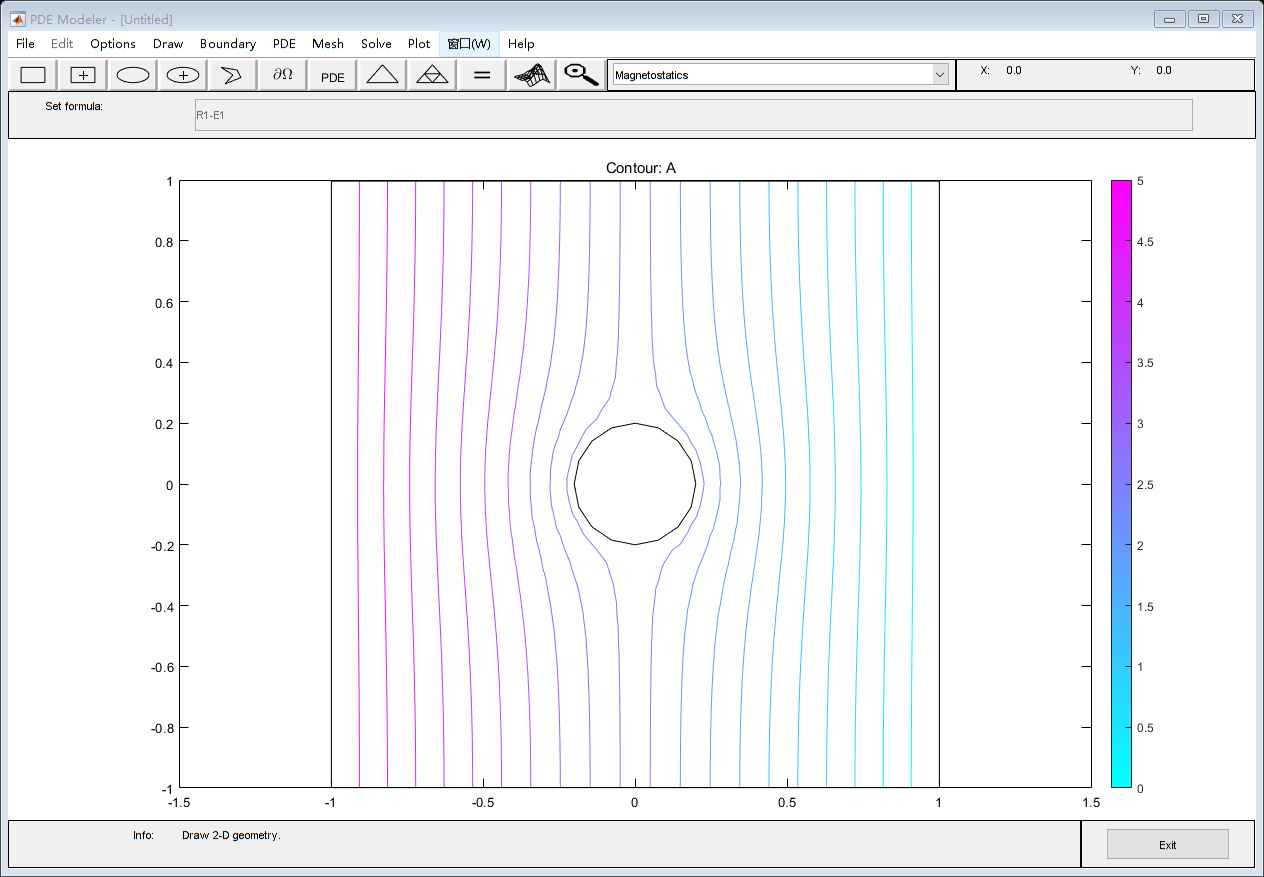

Superconductor

**仿真结果如上所示。可以看出，由于超导圆柱的存在，空间的等势线分布分布不再均匀，磁场进入不到柱体内部。**

function Superconductor
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-0.99876543209876556 1.0012345679012347 0.99629629629629668 -0.99876543209876489],'R1');
    pdeellip(0,0,0.20000000000000001,0.20000000000000001,...
    0,'E1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1./(1.0)',...
    '0.0',...
    '0',...
    '1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0';...
    '0  '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1932','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 0 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end